clear all;

## Onset Conditions

dimension:

N=300;
% correlation paramter:
eta=1;% 1 is symmetric
% amplitude
JAmp=1;
% Sparsity of J
Mdensity=0;
% Tot time 
tot_time=1000;
% Delta t:
Dt=0.1;
% Temperature: Increase it!!!
T=0.01;
% Initialise
J=zeros(N,N);
%x=zeros(N,N_tot);
% ICs
var_ICs_X=0.01;
x(:,1)=var_ICs_X*randn(N,1);
M=sum(x(:,1).^2);
% Fix the constraint sum x^2=N for all t
x(:,1)=x(:,1)*sqrt(N)/sqrt(M);

## ** Compare different methods:**

Sirio code

N_tot=tot_time/Dt;
sirio_time=zeros(1,5);
for j=1:5
    clear J x
    N=50*2^j;
    J=create_couplings(N,JAmp,eta);
    x(:,1)=var_ICs_X*randn(N,1);
    M=sum(x(:,1).^2);
    % Fix the constraint sum x^2=N for all t
    x(:,1)=x(:,1)*sqrt(N)/sqrt(M);
    tic
    for i=2:N_tot
        x(:,i)=x(:,i-1)+Dt*(-x(:,i-1)/N*(x(:,i-1)'*J*x(:,i-1))+J*x(:,i-1))+(eye(N)-1/N*x(:,i-1)*x(:,i-1)')*randn(N,1)*sqrt(2*Dt*T);
    end
    sirio_time(j)=toc;
end


Lagrange multiplier improved 

N_tot=tot_time/Dt;
lagrange_time=zeros(1,5);
for j=1:5
    clear J x
    N=50*2^j;
    J=create_couplings(N,JAmp,eta);
    x(:,1)=var_ICs_X*randn(N,1);
    M=sum(x(:,1).^2);
    % Fix the constraint sum x^2=N for all t
    x(:,1)=x(:,1)*sqrt(N)/sqrt(M);
    tic
    for i=2:N_tot
    z=randn(N,1)*sqrt(2*Dt*T);
    f=Dt*J*x(:,i-1)+z;
    mu=x(:,i-1)'*f/N;
    x(:,i)=x(:,i-1)*(1-mu)+f;
    end
    lagrange_time(j)=toc;
end

constrained dynamics

N_tot=tot_time/Dt;
constrained_time=zeros(1,5);
for j=1:5
    clear J x
    N=50*2^j;
    J=create_couplings(N,JAmp,eta);
    x(:,1)=var_ICs_X*randn(N,1);
    M=sum(x(:,1).^2);
    % Fix the constraint sum x^2=N for all t
    x(:,1)=x(:,1)*sqrt(N)/sqrt(M);
    tic
    for i=2:N_tot
        z=randn(N,1)*sqrt(2*Dt*T);
        f=Dt*J*x(:,i-1)+z;
        x_norm=norm(x(:,i-1))^2;
        %x_norm=N;
        xf=x(:,i-1)'*f;
        x(:,i)=x(:,i-1)*(-xf/x_norm+sqrt((xf/x_norm)^2+(N-norm(f)^2)/x_norm))+f;
    end
    constrained_time(j)=toc;
end

save('time_execution','sirio_time','lagrange_time','constrained_time')

figure()
plot(50*2.^(1:5),sirio_time,'o','MarkerSize',14)
hold on
plot(50*2.^(1:5),lagrange_time,'s','MarkerSize',14)
plot(50*2.^(1:5),constrained_time,'g*','MarkerSize',14)
l={'Reference','impoved','Constrained'};
legend(l,'Location','northwest','FontSize',18)
set(gca, 'XScale','log','YScale', 'log')
xlabel('N','FontSize',18)
ylabel('Time of execution (s)','FontSize',18)
hold off
tightfig()

ans =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [403 246 512.33 398.3]
       Units: 'pixels'

  Show all properties


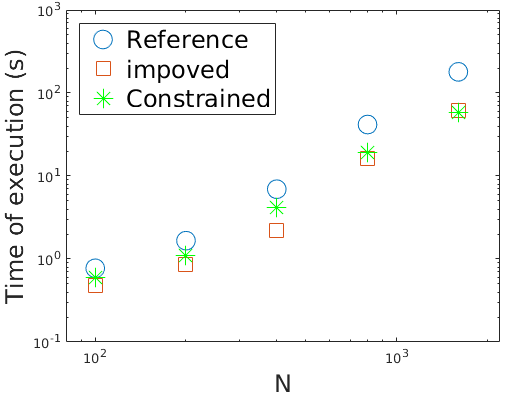

xlim([80,2200])